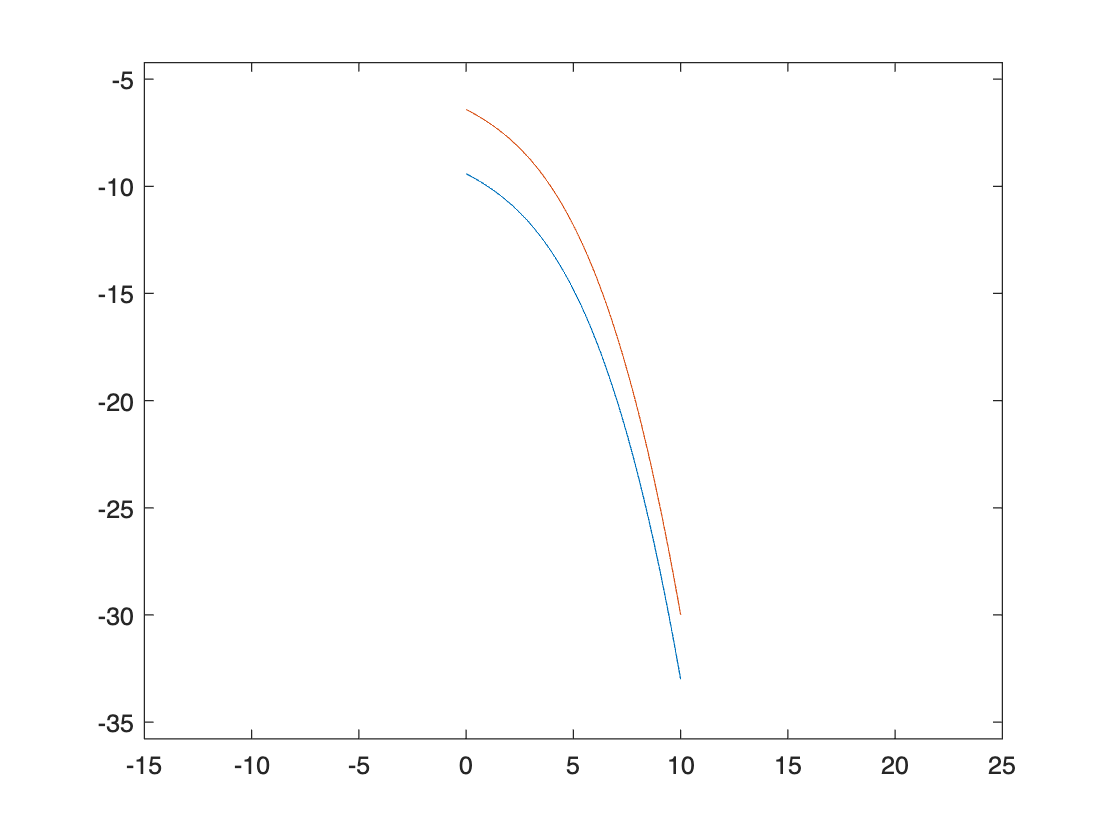

clear;close;clc;

xstart=0;
step=0.01;
xend=10;
x=xstart:step:xend;

trackpara=(2.*rand([1,7])-1).*[1e-6 1e-5 1e-3 1e-2 1e-1 1 1e1];
lowertrack=polyval(trackpara,x);

offset=3;
uppertrack=lowertrack+offset;

figure
plot(x,lowertrack);
hold on
axis padded equal
plot(x,uppertrack)

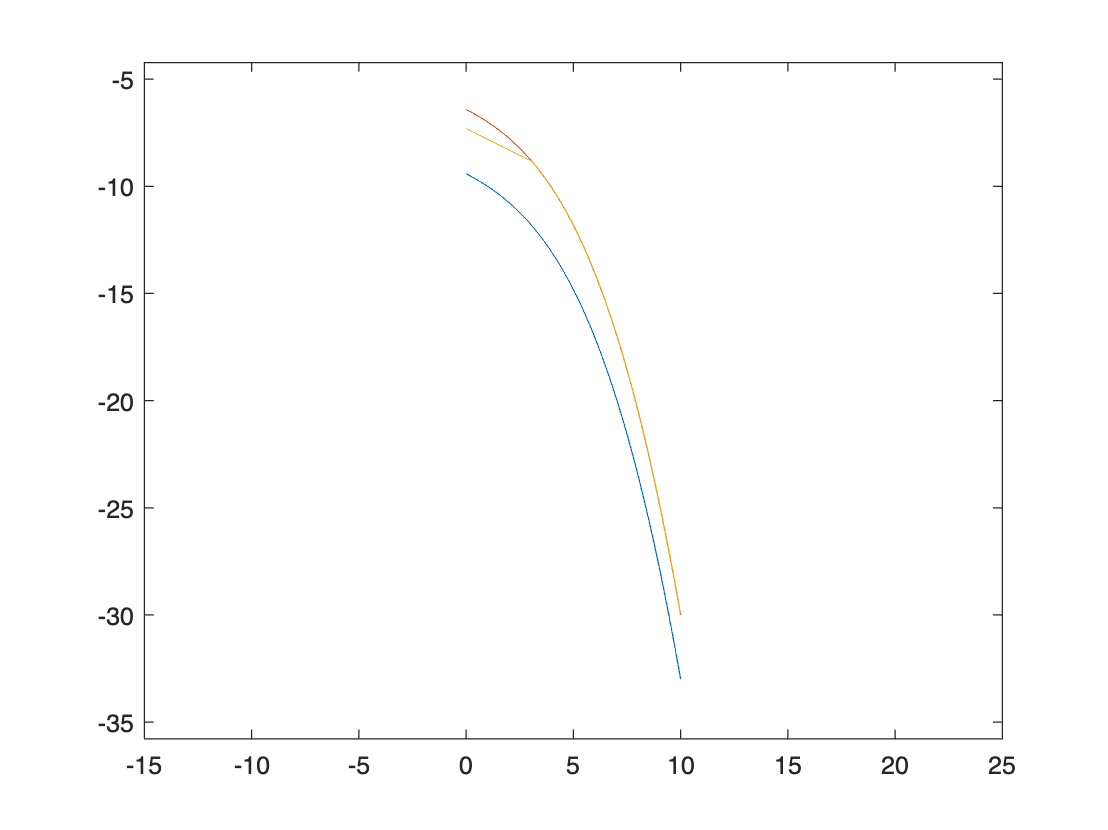

%90deg

startpoint=rand*offset+lowertrack(1);
direction=0.5(lowertrack(1)-lowertrack(2));

traj=startpoint;
i=1;
while(i<length(x))
    newpoint=traj(end)+direction*step;
    while(newpoint<uppertrack(i) && newpoint>lowertrack(i) && i<length(x))
        traj=[traj newpoint];
        newpoint=traj(end)+direction*step;
        i=i+1;
    end
    newpoint=min(newpoint,uppertrack(i));
    newpoint=max(newpoint,lowertrack(i));
    traj=[traj newpoint];
    
    direction=-1/direction;
    i=i+1;
end
plot(x,traj)